clear;
clc;

## Scenario Setup

Describe physical parameters (Load from Base Scenario file)

ScenarioBase();

%For Graphing
GraphZBW = [];
GraphXTime = [];
GraphYSimple = [];
GraphYMaxAoI= [];
GraphYMAB = [];

## Execute Scenario

Prepare Sim: Assume Fixed Delay and Bandwidth, but varying item size

TDelayAtStep = DelayPhysDist;
BRMax = 16; %16[Mbps]
MaxItems = 10;
BRPerStep = BRMax * TimeStep; 

Generate Items (command sent at $t=0$ so sim starts after delay)

ItemList(1) = Item("Photo", 0,  3, 6 * TimeStep, TimeStep * 10);
ItemList(2) = Item("Video", 0,  9, 12 * TimeStep, TimeStep * 2);
ItemList(3) = Item("Loc",   0, 10, 1 * TimeStep, TimeStep);
ItemList(4) = Item("Stats", 0,  5, 3 * TimeStep, TimeStep * 5);
ItemList(5) = Item("LIDAR", 0,  9, 8 * TimeStep, TimeStep * 2);

for i=6:MaxItems
    ItemList(i) = Item(i, 0, rand()*10,  (BRMax * rand() * 0.9) * TimeStep, TimeStep * rand() * 10);
end

ItemCount = numel(ItemList);

At $t=0$ we received a command on the Moon, updates will now start sending from Moon to Earth

Here, we loop through different values of available bandwidth in order to test against increasingly constrained scenarios.


% First-Update-First-Serve (Simple) Method
SendSimple();
% Max(AoI) Method
SendMaxAoI();
% MAB Method
SendMAB();


**Data Processing**

% title("Algorithm Performance with Varying Bandwidth");

YAxisSimple = LoggedSendCountSimple(Iter-1,:);
YAxisMaxAoI = LoggedSendCountMaxAoI(Iter-1,:);
YAxisMAB = LoggedSendCountMAB(Iter-1,:);
XAxis = linspace(1,10,10);

for  i=1:MaxItems
    Prios(i) = ItemList(i).PPsi;
end

**Graphing**

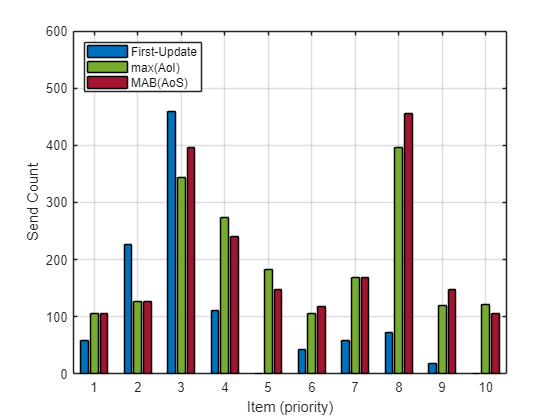

pltLabels = ["First-Update", "max(AoI)", "MAB(AoS)"];
figure(1);
clf();
hold on;
grid on;
box on;
b = bar(XAxis,[YAxisSimple; YAxisMaxAoI; YAxisMAB]);
b(1).FaceColor = "#0072BD";
b(2).FaceColor = "#77AC30";
b(3).FaceColor = "#A2142F";
ylim([0,600]);
xlabel("Item (priority)");
ylabel("Send Count");
legend(pltLabels,"Location","northwest");


tbl = table(linspace(1,10,10)', Prios', YAxisSimple', YAxisMaxAoI', YAxisMAB');

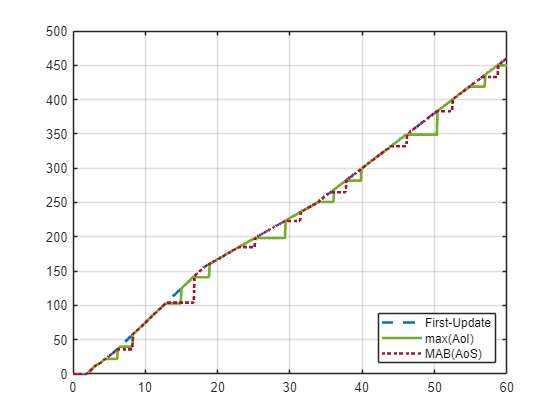

figure(1);
clf();
hold on;
grid on;
box on;
plot(LoggedXTime,LoggedDataSimple(:, 3), '--', Color="#0072BD", LineWidth=2);
plot(LoggedXTime,LoggedDataMaxAoI(:, 3), '-', Color="#77AC30", LineWidth=2);
plot(LoggedXTime,LoggedDataMAB(:, 3), ':', Color="#A2142F", LineWidth=2);
legend(pltLabels,"Location","southeast");